# Regression Model: Welch-Linear for white noise

## Setup:

**Configurate the path and clear the workspace, etc.**

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Input model:

***The input features are described as the power levels found at each frequency bin***

***Directional Resolution of 9 degrees:***

vec = (1:40)';
directions = (0:9:351)';

***Configurations for direction***

index_noise = 1;
% IR Set 
fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
nameIRms = "IR44K_2s_1000ms";
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];


***Select the number of nfft points: defines the frequency resolution***

nfft = 512;

***Run augmentation***

% PSD Welch Method parameters
segmentLength = nfft;        % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
noverlap = segmentLength/2; % 50 percent overlap
win = hamming(segmentLength);% 512 sample-length hanning window
N_bins = (segmentLength/2)+1;

f_500 = ceil(500/(fs/(N_bins*2)));
f_20k = ceil(20000/(fs/(N_bins*2)));
% N_bins = f_20k-f_500+1;

df = fs/(2*((segmentLength/2)+1));
f = 0:df:(fs-df)/2;
N_noise_samples = 100;
N_augmentations = N_noise_samples*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

x_train = zeros(N_bins,N_augmentations);
y_train = zeros(N_augmentations,1);

designSpecs = fdesign.lowpass('Fp,Fst,Ap,Ast', 20000, 22050, 0.01, 80, fs);
F = design(designSpecs);
for k = 1:N_noise_samples
    for i = 1:40
        % Augment noise sample
        if index_noise == 1    % White noise
           noise = randn(fs,1);
           noise = filter(F,noise);
        else                   % Pink noise 
            pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
            noise = pink();
            noise = noise/max(noise);
        end
        index = ((k-1)*40) + i;
        noise_aug = conv(noise,IRms(:,i));
        noise_aug = noise_aug(1:fs);
        
        % cut into 100ms frames with 50% overlap
        noise_windowed_fft  = welch_window(noise_aug,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
        
        % Pyy
        Pxx = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
        x_train(:,index) = normalize(Pxx, 'range');
        y_train(index) = find(any(i==vec,2),1);
    end
end
y_train = directions(y_train);

***Train***

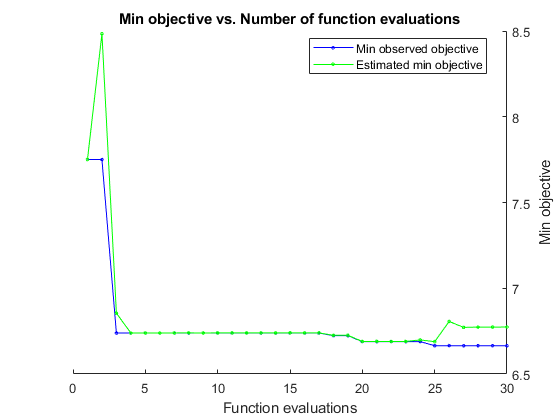

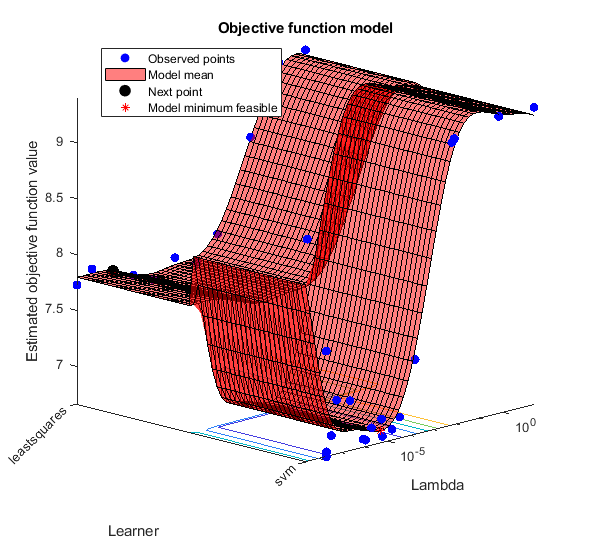

|=====================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      7.7507 |    0.088313 |      7.7507 |      7.7507 |   4.7966e-05 | leastsquares |
|    2 | Accept |      9.2173 |    0.040479 |      7.7507 |      8.4839 |    0.0081569 |          svm |
|    3 | Best   |      6.7388 |    0.050212 |      6.7388 |      6.8545 |   8.3662e-07 |          svm |
|    4 | Accept |      9.1891 |    0.043774 |      6.7388 |       6.739 |     0.006354 |          svm |
|    5 | Accept |      6.8428 |    0.042986 |      6.7388 |      6.7391 |   3.3748e-08 |          svm |
|    6 | Accept |      9.3118 |    0.068208 |      6.7388 |     

Mdl =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [257×1 double]
                 Bias: 163.5002
               Lambda: 5.2978e-06
              Learner: 'svm'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 5.2978e-06
                 Objective: 10.7872
                 PassLimit: 10
                 NumPasses: 10
                BatchLimit: []
             NumIterations: 40000
              GradientNorm: NaN
         GradientTolerance: 0
      RelativeChangeInBeta: 0.0707
             BetaTolerance: 1.0000e-04
             DeltaGradient: 152.0417
    DeltaGradientTolerance: 0.1000
           TerminationCode: 0
         TerminationStatus: {'Iteration limit exceeded.'}
                     Alpha: [4000×1 double]
                   History: []
                   FitTime: 0.0171
                    Solver: {'dual'}


HyperparameterOptimizationResults =   BayesianOptimization with properties:

                      ObjectiveFcn: @createObjFcn/inMemoryObjFcn
              VariableDescriptions: [3×1 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: 6.6651
                   XAtMinObjective: [1×2 table]
             MinEstimatedObjective: 6.7738
          XAtMinEstimatedObjective: [1×2 table]
           NumObjectiveEvaluations: 30
                  TotalElapsedTime: 34.8471
                         NextPoint: [1×2 table]
                            XTrace: [30×2 table]
                    ObjectiveTrace: [30×1 double]
                  ConstraintsTrace: []
                     UserDataTrace: {30×1 cell}
      ObjectiveEvaluationTimeTrace: [30×1 double]
                IterationTimeTrace: [30×1 double]
                        ErrorTrace: [30×1 double]
                  Fea

% Rename variables for clarity:
%   X: Predictor data (rows are observations)
%   Y: Response data
X = x_train;
Y = y_train';

hyperopts = struct('AcquisitionFunctionName','expected-improvement-plus', 'Holdout', 0.3);
[Mdl,FitInfo,HyperparameterOptimizationResults] = fitrlinear(X,Y,'ObservationsIn','columns',...
    'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',hyperopts)

## Evaluation

epsTrain = loss(Mdl,X,Y,'ObservationsIn', 'columns','LossFun', 'epsiloninsensitive');
display("Training loss: " + epsTrain)

    "Training loss: 9.4436"



## Test on same reverberation duration

***Augment test samples***

N_tests = 10;
N_augmentations = N_tests*IRLen;

x_test = zeros(N_bins,N_augmentations);
y_test = zeros(N_augmentations,1);

for k = 1:N_tests
    for i = 1:40
        if index_noise == 1    % White noise
           noise = randn(fs,1);
           noise = filter(F,noise);
        else                   % Pink noise 
            pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
            noise = pink();
            noise = noise/max(noise);
        end
        index = ((k-1)*40) + i;
        noise_aug = conv(noise,IRms(:,i));
        noise_aug = noise_aug(1:fs);
        
        % cut into 100ms frames with 50% overlap
        noise_windowed_fft  = welch_window(noise_aug,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
        
        % Pyy
        Pxx = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
        x_test(:,index) = normalize(Pxx, 'range');
        y_test(index) = find(any(i==vec,2),1);
    end
end

y_test =directions(y_test);

***Predict test samples***

epsTest = loss(Mdl,x_test',y_test','LossFun', 'epsiloninsensitive');
disp("Test loss: " + epsTest);

Test loss: 9.8376


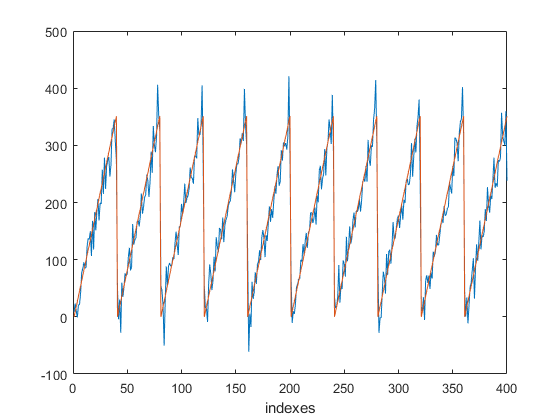

yHatTest = predict(Mdl,x_test');
%yHatTest(yHatTest > 360) = yHatTest(yHatTest >360) - 360;
yErrorTest = mean(abs(y_test-yHatTest).^2);
figure;
plot(yHatTest); hold on; plot(y_test); xlabel("indexes");

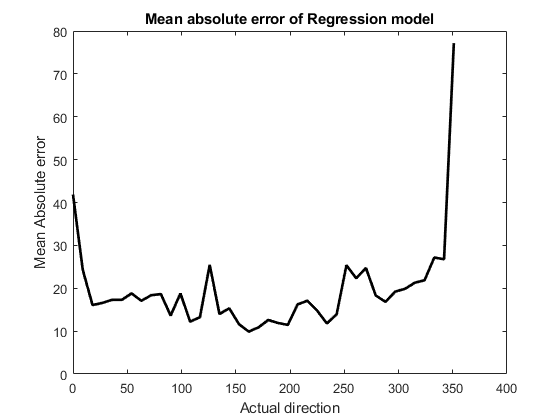

yErrorTest_averaged = zeros(40,1);
yTest_averaged = zeros(40,1);
for i = 1:40
    yHatTestDirection = yHatTest(i:40:end); % Every 40 samples the same direction returns in the vector y_test
    yTest_averaged(i) = mean(yHatTestDirection);
    
    yErrorTest_averaged(i) = mean(abs(directions(i)-yHatTestDirection));
end
figure;
plot(directions,yErrorTest_averaged, "k", "LineWidth", 2); xlabel("Actual direction"); ylabel("Mean Absolute error"); title("Mean absolute error of Regression model");

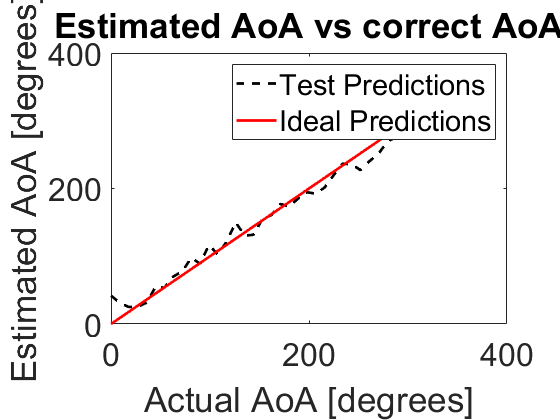

figure;
plot(directions,yTest_averaged, "k--", "LineWidth", 2); hold on; plot(directions,directions, "r-", "LineWidth", 2); xlabel("Actual AoA [degrees]"); ylabel("Estimated AoA [degrees]"); title("Estimated AoA vs correct AoA", "FontSize",3);
ax = gca;
ax.FontSize = 24;
legend("Test Predictions", "Ideal Predictions");

## Test on augmented noise with other reverberations

***Load in other IR set***

fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
N_tests = 10;
N_augmentations = N_tests*IRLen;
yHatTest = zeros(N_augmentations,5);
yErrorTest = zeros(N_augmentations,5);
names = ["IR44K_2s_10ms";
"IR44K_2s_50ms";
"IR44K_2s_100ms";
"IR44K_2s_500ms";
"IR44K_2s_1000ms"];
for index_IR = 1:5
    IR_reverb = struct2cell(load(dir+names(index_IR)));
    IR_reverb = IR_reverb{1};
    IR_reverb =IR_reverb(:,2);
    IR_reverb = [IR_reverb{:}];
    
    
    x_test_reverb = zeros(N_bins,N_augmentations);
    y_test_reverb = zeros(N_augmentations,1);
    
    for k = 1:N_tests
        for i = 1:40
            % Augment noise sample
            if index_noise == 1    % White noise
               noise = randn(fs,1);
               noise = filter(F,noise);
            else                   % Pink noise 
                pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
                noise = pink();
                noise = noise/max(noise);
            end
            index = ((k-1)*40) + i;
            noise_aug = conv(noise,IRms(:,i));
            noise_aug = noise_aug(1:fs);
            
            % cut into 100ms frames with 50% overlap
            noise_windowed_fft  = welch_window(noise_aug,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
            
            % Pyy
            Pxx = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
            x_test_reverb(:,index) = normalize(Pxx, 'range');
            y_test_reverb(index) = find(any(i==vec,2),1);
        end
    end
    
    y_test_reverb = directions(y_test_reverb);

***Predict test samples***

    epsTest = loss(Mdl,x_test_reverb',y_test_reverb', 'LossFun', 'epsiloninsensitive');
    disp("Test loss: " + epsTest);
    yHatTest(:,index_IR) = abs(predict(Mdl,x_test_reverb'));
    yErrorTest(:,index_IR) = mean(abs(y_test_reverb-yHatTest(:,index_IR)).^2);
end

Test loss: 10.3339
Test loss: 9.9318
Test loss: 10.5034
Test loss: 10.0203
Test loss: 10.547


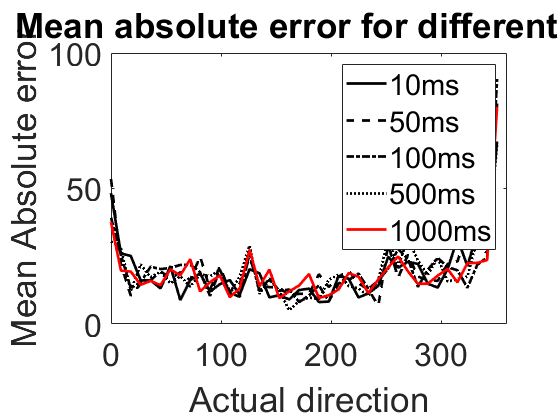

yErrorTest_averaged = zeros(40,5);
yTest_averaged = zeros(40,5);
figure;
lines = ["-"; "--"; "-."; ":"; "-"];
colors = ["k"; "k"; "k"; "k"; "r"];
for k = 1:5
    for i = 1:40
        yHatTestDirection = yHatTest(i:40:end,k); % Every 40 samples the same direction returns in the vector y_test
        yTest_averaged(i,k) = mean(yHatTestDirection);
        
        yErrorTest_averaged(i,k) = mean(abs(directions(i)-yHatTestDirection));
    end
    plot(directions,yErrorTest_averaged(:,k), "Color", colors(k), "LineStyle", lines(k), "LineWidth", 2); hold on
end
xlabel("Actual direction"); ylabel("Mean Absolute error"); title("MAE Singular trained model", "FontSize",36);
xlim([0 360]);
ax = gca;
ax.FontSize = 24;
legend("10ms", "50ms", "100ms", "500ms", "1000ms");

## Model training with different reverberations

IRLen = 40;
fs = 44100;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth

% IR Set with Duration = 1000ms
nameIR1000ms = 'IR44K_2s_1000ms';
IR1000ms = load(dir+nameIR1000ms).IR44K_2s_1000ms;
IR1000ms =IR1000ms(:,2);
IR1000ms = [IR1000ms{:}];

% IR Set with Duration = 500ms
nameIR500ms = 'IR44K_2s_500ms';
IR500ms = load(dir+nameIR500ms).IR44K_2s_500ms;
IR500ms =IR500ms(:,2);
IR500ms = [IR500ms{:}];

% IR Set with Duration = 100ms
nameIR100ms = 'IR44K_2s_100ms';
IR100ms = load(dir+nameIR100ms).IR44K_2s_100ms;
IR100ms =IR100ms(:,2);
IR100ms = [IR100ms{:}];

% IR Set with Duration = 50ms
nameIR50ms = 'IR44K_2s_50ms';
IR50ms = load(dir+nameIR50ms).IR44K_2s_50ms;
IR50ms =IR50ms(:,2);
IR50ms = [IR50ms{:}];

% IR Set with Duration = 10ms
nameIR10ms = 'IR44K_2s_10ms';
IR10ms = load(dir+nameIR10ms).IR44K_2s_10ms;
IR10ms =IR10ms(:,2);
IR10ms = [IR10ms{:}];

IR_set = {IR10ms; IR50ms;IR100ms;IR500ms;IR1000ms};

***Train a model with 10 samples from each reverb model, from each direction***

n_samples = 20;
n_reverbs = 5;
n_augmentations = n_samples*n_reverbs*IRLen;

x_train_reverb = zeros(N_bins, n_augmentations);
y_train_reverb = zeros(n_augmentations,1);
index = 1;
for n = 1:5
    IR = IR_set{n};
    for k = 1:n_samples
        for i = 1:40
            % Augment noise sample
            if index_noise == 1    % White noise
               noise = randn(fs,1);
               noise = filter(F,noise);
            else                   % Pink noise 
                pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
                noise = pink();
                noise = noise/max(noise);
            end
            noise_aug = conv(noise,IRms(:,i));
            noise_aug = noise_aug(1:fs);
            
            % cut into 100ms frames with 50% overlap
            noise_windowed_fft  = welch_window(noise_aug,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
            
            % Pyy
            Pxx = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
            x_train_reverb(:,index) = normalize(Pxx, 'range');
            y_train_reverb(index) = find(any(i==vec,2),1);
            index = index+1;
        end
    end
end
y_train_reverb = directions(y_train_reverb);

***Train***

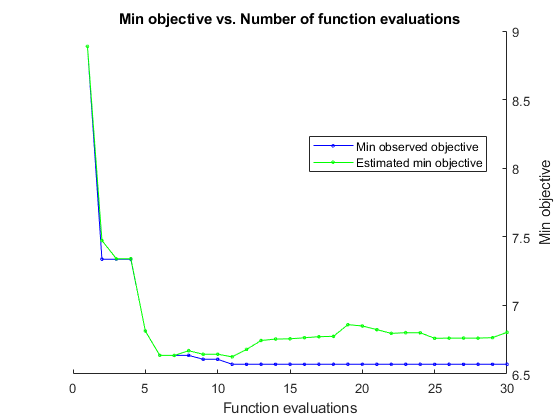

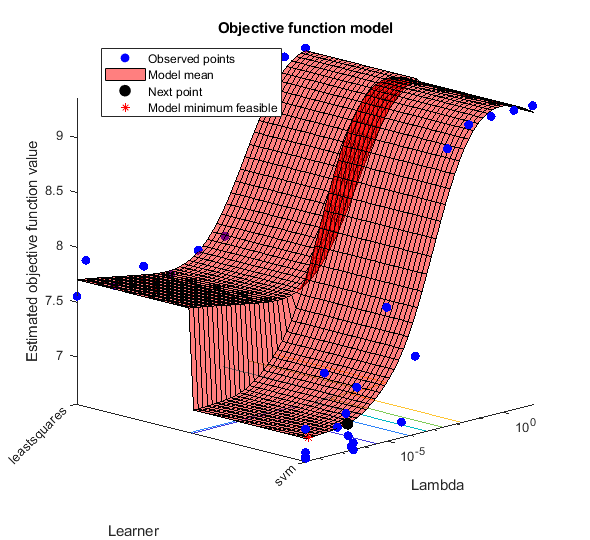

|=====================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      8.8886 |     0.32716 |      8.8886 |      8.8886 |      0.19962 | leastsquares |
|    2 | Best   |      7.3367 |    0.050689 |      7.3367 |      7.4733 |   1.6796e-08 |          svm |
|    3 | Accept |      9.2958 |    0.034306 |      7.3367 |      7.3398 |       21.608 |          svm |
|    4 | Accept |      7.6732 |    0.084839 |      7.3367 |      7.3404 |   2.0606e-06 | leastsquares |
|    5 | Best   |      6.8131 |    0.049078 |      6.8131 |      6.8134 |    6.263e-08 |          svm |
|    6 | Best   |      6.6354 |    0.043508 |      6.6354 |     

Mdl =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [257×1 double]
                 Bias: 162.2196
               Lambda: 6.2630e-08
              Learner: 'svm'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 6.2630e-08
                 Objective: 9.3558
                 PassLimit: 10
                 NumPasses: 10
                BatchLimit: []
             NumIterations: 40000
              GradientNorm: NaN
         GradientTolerance: 0
      RelativeChangeInBeta: 0.0773
             BetaTolerance: 1.0000e-04
             DeltaGradient: 197.3282
    DeltaGradientTolerance: 0.1000
           TerminationCode: 0
         TerminationStatus: {'Iteration limit exceeded.'}
                     Alpha: [4000×1 double]
                   History: []
                   FitTime: 0.0158
                    Solver: {'dual'}


HyperparameterOptimizationResults =   BayesianOptimization with properties:

                      ObjectiveFcn: @createObjFcn/inMemoryObjFcn
              VariableDescriptions: [3×1 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: 6.5709
                   XAtMinObjective: [1×2 table]
             MinEstimatedObjective: 6.8038
          XAtMinEstimatedObjective: [1×2 table]
           NumObjectiveEvaluations: 30
                  TotalElapsedTime: 40.9876
                         NextPoint: [1×2 table]
                            XTrace: [30×2 table]
                    ObjectiveTrace: [30×1 double]
                  ConstraintsTrace: []
                     UserDataTrace: {30×1 cell}
      ObjectiveEvaluationTimeTrace: [30×1 double]
                IterationTimeTrace: [30×1 double]
                        ErrorTrace: [30×1 double]
                  Fea

% Rename variables for clarity:
%   X: Predictor data (rows are observations)
%   Y: Response data
X = x_train;
Y = y_train';

hyperopts = struct('AcquisitionFunctionName','expected-improvement-plus', 'Holdout', 0.3);
[Mdl,FitInfo,HyperparameterOptimizationResults] = fitrlinear(X,Y,'ObservationsIn','columns',...
    'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',hyperopts)

## Evaluation

epsTrain = loss(Mdl,X,Y,'ObservationsIn', 'columns','LossFun', 'epsiloninsensitive');
display("Training loss: " + epsTrain)

    "Training loss: 9.3399"



***Case 1: Low errors***

***    If the validation error is higher than the training error this indicates that there is a case of HIGH VARIANCE***

***    High variance can be solved by adding more training data***

***Case 2: High errors***

***    If both the validation and training error are high this indicates a case of HIGH BIAS***

***    High bias asks for more distinct features***

## Test on augmented noise with other reverberations

***Load in other IR set***

fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
test_acc = zeros(5,1);
names = ["IR44K_2s_10ms";
"IR44K_2s_50ms";
"IR44K_2s_100ms";
"IR44K_2s_500ms";
"IR44K_2s_1000ms"];
    N_tests = 10;
    N_augmentations = N_tests*IRLen;
yHatTest = zeros(N_augmentations,5);
yErrorTest = zeros(N_augmentations,5);
for index_IR = 1:5

    IR_reverb = struct2cell(load(dir+names(index_IR)));
    IR_reverb = IR_reverb{1};
    IR_reverb =IR_reverb(:,2);
    IR_reverb = [IR_reverb{:}];
    
    x_test_reverb = zeros(N_bins,N_augmentations);
    y_test_reverb = zeros(N_augmentations,1);
    
    for k = 1:N_tests
        for i = 1:40
            % Augment noise sample
            if index_noise == 1    % White noise
               noise = randn(fs,1);
               noise = filter(F,noise);
            else                   % Pink noise 
                pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
                noise = pink();
                noise = noise/max(noise);
            end
            index = ((k-1)*40) + i;
            noise_aug = conv(noise,IRms(:,i));
            noise_aug = noise_aug(1:fs);
            
            % cut into 100ms frames with 50% overlap
            noise_windowed_fft  = welch_window(noise_aug,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
            
            % Pyy
            Pxx = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
            x_test_reverb(:,index) = normalize(Pxx, 'range');
            y_test_reverb(index) = find(any(i==vec,2),1);
        end
    end
    y_test_reverb = directions(y_test_reverb);

***Predict test samples***

    epsTest = loss(Mdl,x_test_reverb',y_test_reverb', 'LossFun', 'epsiloninsensitive');
    disp("Test loss: " + epsTest);
    yHatTest(:,index_IR) = abs(predict(Mdl,x_test_reverb'));
    yErrorTest(:,index_IR) = mean(abs(y_test_reverb-yHatTest(:,index_IR)).^2);
end

Test loss: 10.0703
Test loss: 10.0287
Test loss: 10.8799
Test loss: 9.1706
Test loss: 9.3269


## Visualize the results

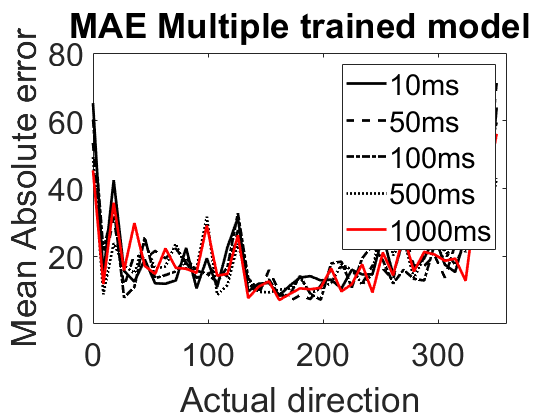

yErrorTest_averaged = zeros(40,5);
yTest_averaged = zeros(40,5);
figure;
lines = ["-"; "--"; "-."; ":"; "-"];
colors = ["k"; "k"; "k"; "k"; "r"];
for k = 1:5
    for i = 1:40
        yHatTestDirection = yHatTest(i:40:end,k); % Every 40 samples the same direction returns in the vector y_test
        yTest_averaged(i,k) = mean(yHatTestDirection);
        
        yErrorTest_averaged(i,k) = mean(abs(directions(i)-yHatTestDirection));
    end
    plot(directions,yErrorTest_averaged(:,k), "Color", colors(k), "LineStyle", lines(k), "LineWidth", 2); hold on
end
xlabel("Actual direction"); ylabel("Mean Absolute error"); title("MAE Multiple trained model", "FontSize",36);
xlim([0 360]);
ax = gca;
ax.FontSize = 24;
legend("10ms", "50ms", "100ms", "500ms", "1000ms");